# Eigen Decomposition

% Symmetric Matrix
X = randn(20);
S = X * X';

[eigvecs, eigvals] = eig(S)

eigvecs =     0.2617    0.0184    0.3099    0.2611    0.0438    0.2388    0.2974    0.1264   -0.1659   -0.0983    0.0804    0.3680    0.0837   -0.2202   -0.3238    0.0990   -0.1782    0.2902   -0.3422   -0.1461
    0.1357    0.2528   -0.0318   -0.0013    0.0695    0.0441    0.2749   -0.1338   -0.3601    0.2816    0.0082    0.2004    0.0267    0.0458    0.2037   -0.5822    0.4004    0.0562    0.0224    0.1415
   -0.1399   -0.4283   -0.3087    0.0059   -0.1360   -0.0210   -0.0099    0.0942   -0.1509   -0.3143    0.0194    0.1030   -0.2550    0.4439   -0.1710   -0.4002   -0.1020    0.1634   -0.1844   -0.1365
    0.0061   -0.0976   -0.1623    0.1031    0.0624   -0.1828   -0.0462    0.2016    0.0100   -0.1057    0.4014    0.3292   -0.0138    0.0922    0.4520    0.3873    0.3162    0.3517    0.0496    0.0591
    0.0197   -0.2116   -0.1952    0.3821   -0.2516    0.4261   -0.0235   -0.1448    0.1110    0.1494    0.0992   -0.3433   -0.1871   -0.2424    0.1979   -0.0196    0.0331    0.1113   -0.

eigvals =     0.0011         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0415         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.6122         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.8964         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.7757         0         0         0         0         0         0         0         0         0         0         0         0         0      

% check magnitude of each eigen vectors (They are unit vectors)
sqrt( sum(eigvecs.^2, 1))

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


## make plots

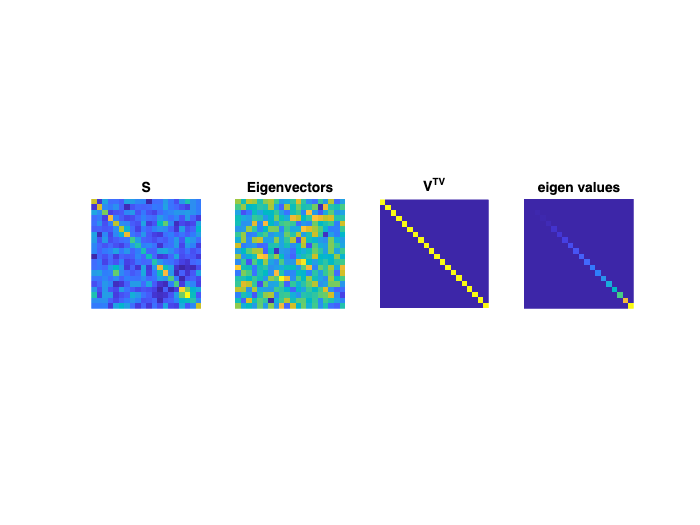


figure(1), clf
subplot(141), imagesc(S)
axis square, axis off
title('S')

subplot(142), imagesc(eigvecs)
axis square, axis off
title('Eigenvectors')

% Dot Product and Orthogonality: The dot product between each pair of eigenvectors, denoted by \( V^TV \), yields 0 due to their orthogonality property. 
% Orthogonal vectors have a dot product of 0.
% Diagonal Elements: Since the dot product of a vector with itself gives the squared magnitude, the diagonal elements of the resulting matrix will be precisely 1. 
% This is because the eigenvectors are normalized to unit length.
% Resulting Matrix: Due to the orthogonality property, the resulting matrix is an identity matrix \( I \). 
subplot(143), imagesc(eigvecs'*eigvecs)
axis square, axis off
title('V^TV')

subplot(144), imagesc(eigvals)
axis square, axis off
title('eigen values')